# CIELAB

Github Link: [https://github.com/pratheepkumar1/Principles-of-Color-Science/tree/main/Assignment%206%20CIELAB](https://github.com/pratheepkumar1/Principles-of-Color-Science/tree/main/Assignment%206%20CIELAB)

- Started by reading the given dataset (ColorChecker spectra, standard illuminant data, standard observers, and the CIE 1931 chromaticity coordinates)

- Interpolated the essential dataset to wavelength (380 to 780 with 5nm difference)

- Calculated the d_lamda (change in wavelength)

% Reading the Dataset
warning('off','all');
xyz_std_obs_two_deg_dataset = readtable("StdObsFuncs.xlsx",Sheet="2-degree");
xyz_std_obs_ten_deg_dataset = readtable("StdObsFuncs.xlsx",Sheet="10-degree");
source_dataset = readtable("Illuminant Data.xlsx");
patch_dataset = readtable("MacbethColorChecker.xlsx");
cc_spectral_locus_dataset = readtable("TwoDegChromaticity.xlsx");


% Create a interpolated data for the datasets
intp_wavelength_info = struct('min',380,'max',780,'range',5);

xyz_std_obs_two_deg = interpolateData(xyz_std_obs_two_deg_dataset{:,1},...
    xyz_std_obs_two_deg_dataset{:,2:end},intp_wavelength_info);
xyz_std_obs_ten_deg = interpolateData(xyz_std_obs_ten_deg_dataset{:,1},...
    xyz_std_obs_ten_deg_dataset{:,2:end},intp_wavelength_info);
patches = patch_dataset{2:end,2:25};

%Calculate change in Wavlength
wavelength = patch_dataset{2:end,1};
d_lambda = mean(diff(wavelength));

### Question 1: 

Calculate CIE XYZ tristimulus values and chromaticity coordinates for each ColorChecker patch using the CIE standard D50 illuminant and each of the 2-deg and 10-deg standard observers. Please put these in a table, one row per patch.

**Steps:**

- Interpolated the illuminant D50.

- Calculated tristimulus using the below equation (written as function at the end)

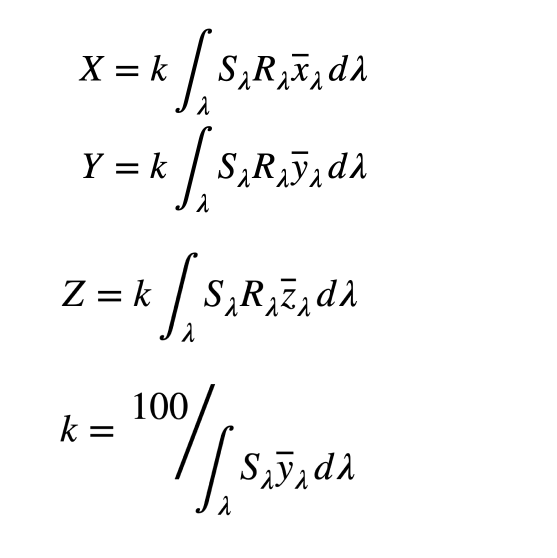

- Calculated chromaticity coordinates for all patches under D50 light source with 2 and 10 degree viewing angle using the below equation (written as function at the end)

 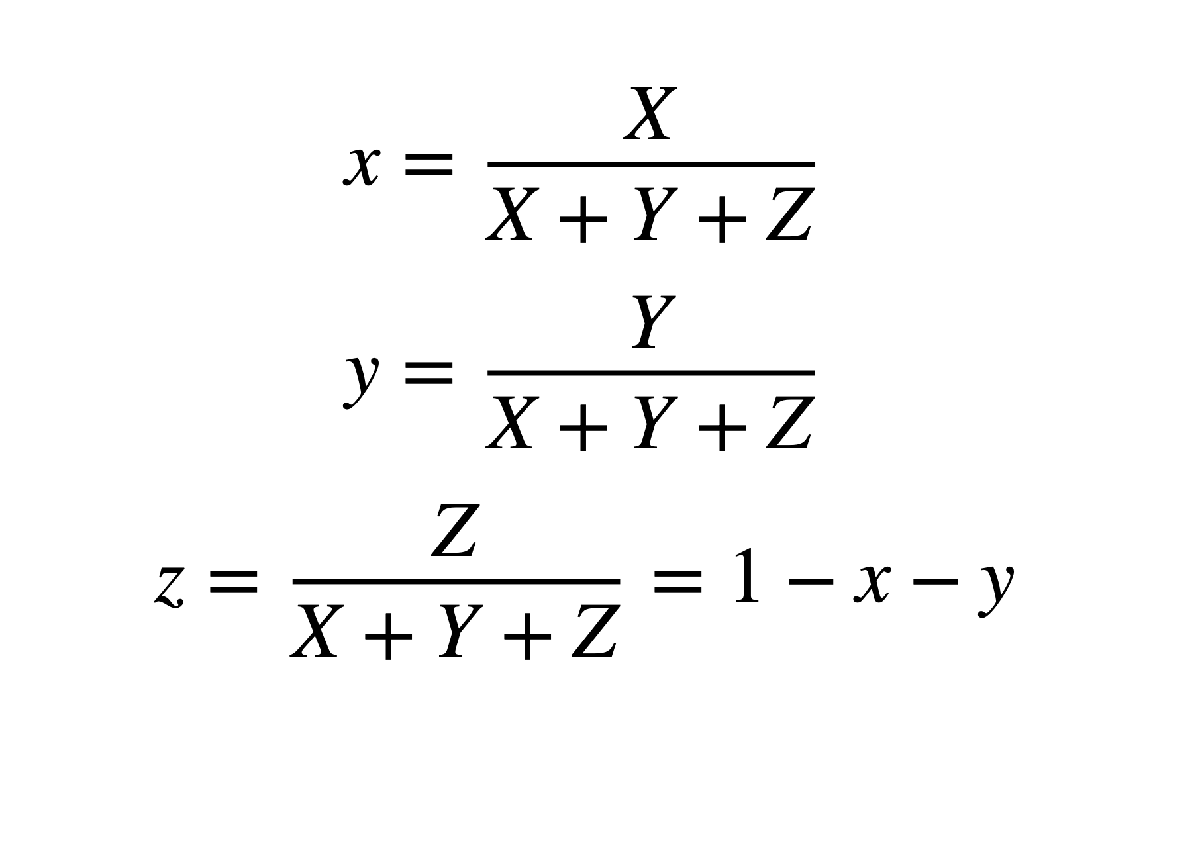

%Get spectral radiance of Source D50
sources_D50 = interpolateData(source_dataset{:,1},source_dataset.D50,...
    intp_wavelength_info);

% Tristimulus value for all patches in D50 Source for 2 and 10 degree observer
tristimulus_XYZ_D50_two_deg = calcTristimulus(xyz_std_obs_two_deg,sources_D50,...
    patches,d_lambda);
tristimulus_XYZ_D50_ten_deg = calcTristimulus(xyz_std_obs_ten_deg,sources_D50,...
    patches,d_lambda);

table_XYZ_D50_two_deg = createTablexyz(tristimulus_XYZ_D50_two_deg)

table_XYZ_D50_two_deg = 24×3 table
      x         y         z   
    ______    ______    ______

    11.685    9.9849    4.5822
    40.346    36.275    19.879
    17.139    18.712    26.029
    10.457    12.968    5.1534
    25.431    24.165    34.136
    30.913    41.829    34.404
    39.678    30.819    4.5147
      12.3    11.375    28.007
    30.953    20.351    10.363
    8.6358    6.5933    10.844
     34.94    43.792    8.8882
    49.827    44.645    6.5358
    7.3247    5.9081    22.632
    14.754    23.229    7.4667
    22.639    12.864      3.93
    60.361    60.973     7.677


table_XYZ_D50_ten_deg = createTablexyz(tristimulus_XYZ_D50_ten_deg)

table_XYZ_D50_ten_deg = 24×3 table
      x         y         z   
    ______    ______    ______

    11.435    9.7396    4.5283
    39.584    35.842    19.284
    17.431    19.321    25.928
    10.641    12.599    4.9522
    25.332    25.009    34.038
    31.778    42.313    33.179
    38.623    29.339    4.3717
    12.378    12.377    28.003
    29.555    19.973    10.321
     8.472    6.7702    11.129
    35.575    42.171    8.0876
    49.106    42.512     6.175
    7.3488    6.8241    22.561
    15.483    22.573    6.9538
    21.136    12.476    3.8907
    59.968     58.37    6.8138



% chromacity_coordinates for all patches in D50 Source for 2 and 10 degree observer
cc_D50_two_deg = calChromacityCoordinates(tristimulus_XYZ_D50_two_deg);
cc_D50_ten_deg = calChromacityCoordinates(tristimulus_XYZ_D50_ten_deg);

### Question 1: Answer 

table_cc_D50_two_deg = createTablexyz(cc_D50_two_deg)

table_cc_D50_two_deg = 24×3 table
       x          y          z    
    _______    _______    ________

     0.4451    0.38035     0.17455
    0.41809    0.37591       0.206
    0.27698    0.30239     0.42063
    0.36592    0.45375     0.18032
    0.30372     0.2886     0.40768
    0.28851    0.39039     0.32109
    0.52896    0.41086    0.060186
      0.238     0.2201      0.5419
    0.50193    0.33001     0.16805
    0.33121    0.25288     0.41591
    0.39877    0.49979     0.10144
     0.4933      0.442    0.064706
    0.20423    0.16473     0.63104
    0.32462    0.51109     0.16428
    0.57412    0.32621    0.099662
    0.46788    0.47262    0.059506


table_cc_D50_ten_deg = createTablexyz(cc_D50_ten_deg)

table_cc_D50_ten_deg = 24×3 table
       x          y          z    
    _______    _______    ________

     0.4449    0.37893     0.17618
    0.41794    0.37844     0.20361
     0.2781    0.30825     0.41366
    0.37745     0.4469     0.17565
    0.30022    0.29639     0.40339
    0.29624    0.39445     0.30931
    0.53395    0.40561    0.060438
    0.23462    0.23461     0.53077
    0.49382    0.33372     0.17246
    0.32126    0.25672     0.42202
    0.41446    0.49131    0.094225
    0.50214    0.43471    0.063144
    0.20005    0.18577     0.61418
      0.344    0.50151     0.15449
    0.56358    0.33268     0.10375
    0.47916     0.4664    0.054444


### Question 2

Calculate CIE XYZ tristimulus values and chromaticity coordinates for each ColorChecker patch using the CIE 2-deg standard observer and the A and D65 illuminants. Please put these in a table, one row per patch.

**Steps:**

- Same as the previous question except the illuminants are change

%Get spectral radiance of Source A and Source D65
sources_A = interpolateData(source_dataset{:,1},source_dataset.A,...
    intp_wavelength_info);
sources_D65 = interpolateData(source_dataset{:,1},source_dataset.D65,...
    intp_wavelength_info);


% Tristimulus value for all patches in Source A and Source D65 for 2 degree observer
tristimulus_XYZ_A_two_deg = calcTristimulus(xyz_std_obs_two_deg,sources_A,...
    patches,d_lambda);
tristimulus_XYZ_D65_two_deg = calcTristimulus(xyz_std_obs_two_deg,sources_D65,...
    patches,d_lambda);

% chromacity_coordinates for patches in Source A and Source D65 for 2 degree observer
cc_A_two_deg = calChromacityCoordinates(tristimulus_XYZ_A_two_deg);
cc_D65_two_deg = calChromacityCoordinates(tristimulus_XYZ_D65_two_deg);

### Question 2: Answer

table_cc_A_two_deg = createTablexyz(cc_A_two_deg)

table_cc_A_two_deg = 24×3 table
       x          y          z    
    _______    _______    ________

    0.53276    0.39554    0.071702
    0.51389    0.39629    0.089821
    0.37764     0.3822     0.24015
    0.44714    0.46742    0.085437
     0.4212    0.35989     0.21891
    0.37688    0.44579     0.17734
     0.5768    0.40073    0.022464
    0.34041    0.31029     0.34929
    0.58765    0.34941    0.062938
    0.46577    0.32627     0.20796
    0.46518    0.48605    0.048778
    0.54705    0.42678    0.026169
    0.28759    0.25133     0.46108
    0.39067     0.5233    0.086033
     0.6364    0.33018    0.033418
    0.52561    0.44737    0.027018


table_cc_D65_two_deg = createTablexyz(cc_D65_two_deg)

table_cc_D65_two_deg = 24×3 table
       x          y          z    
    _______    _______    ________

    0.41045    0.36302     0.22653
    0.38265    0.35706     0.26029
    0.24982    0.26693     0.48324
    0.33936    0.43594      0.2247
    0.27036    0.25518     0.47446
    0.26347    0.35992     0.37661
    0.50858    0.40903    0.082389
    0.21497    0.18838     0.59665
    0.46321    0.31295     0.22384
    0.29037     0.2182     0.49143
    0.37703    0.49584     0.12712
    0.47253    0.44127    0.086193
    0.18841    0.13954     0.67205
     0.3047    0.49527     0.20003
    0.54235    0.31789     0.13977
    0.44752     0.4762     0.07628


table_xyz_D65_two_deg = createTablexyz(tristimulus_XYZ_D65_two_deg)

table_xyz_D65_two_deg = 24×3 table
      x         y         z   
    ______    ______    ______

    10.971    9.7028    6.0547
    38.133    35.583    25.939
    17.857     19.08    34.542
    10.108    12.985     6.693
    25.832    24.381    45.333
    31.279     42.73    44.712
    36.464    29.326    5.9071
    13.417    11.757    37.239
    28.459    19.227    13.752
    8.6809    6.5231    14.692
    33.198     43.66    11.193
    46.184    43.129    8.4243
     8.412    6.2303    30.006
    14.501    23.571    9.5199
    20.176    11.825    5.1994
    56.047    59.638    9.5532


table_xyz_A_two_deg = createTablexyz(tristimulus_XYZ_A_two_deg)

table_xyz_A_two_deg = 24×3 table
      x         y         z   
    ______    ______    ______

    14.787    10.978    1.9901
    50.264    38.761    8.7855
    17.372    17.582    11.047
    12.148    12.699    2.3211
    27.831     23.78    14.465
    32.565     38.52    15.323
    51.771    35.968    2.0163
    11.416    10.406    11.714
    41.201    24.498    4.4127
    9.9537    6.9724    4.4442
     41.58    43.445      4.36
    63.453    49.503    3.0353
    5.8693    5.1292      9.41
    16.053    21.504    3.5353
    32.145    16.678     1.688
    76.201    64.859     3.917


### Question 3

Plot all of your 2-deg (x,y) results (for Illum A, D50, and D65) on a chromaticity diagram, with a legend to make it clear which points go with which illuminant. You can label the points (1-24) using the **text** function in Matlab, and you can plot the spectrum locus using the (x,y) coordinates provided. In chromaticity diagrams, it is important to scale the x-axis and y-axis equally (*think about why*). In Matlab please use the command **axis equal**.

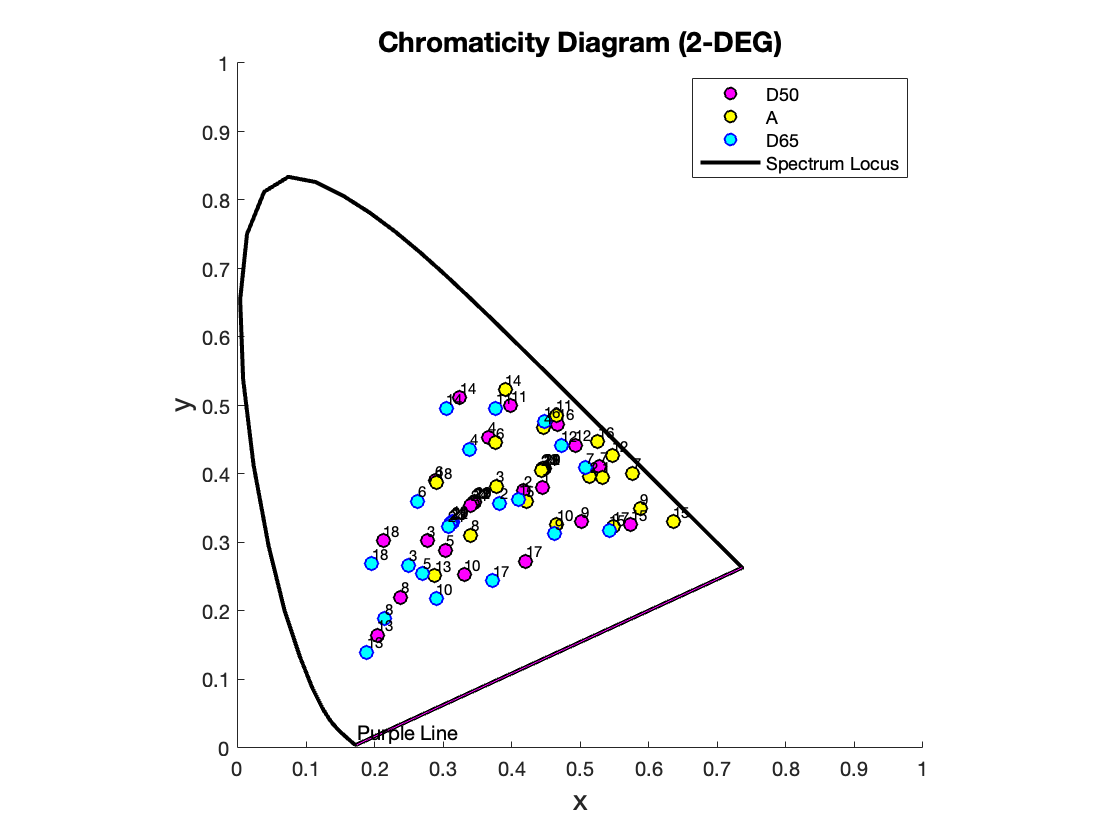

%Creating a line between the spectrum locus's curve initial and 
%end points. 
x = [0.174 0.7368];
y = [0.0048 0.2632];

figure;
labels_a = {'1','2','3','4','5','6','7','8','9','10','11','12','13','14','15','16','17','18','19','20','21','22','23','24'};
labels_b = {'Spectrum Locus'};
%labels_c = {'380','385','390','395','400','405','410','415','420','425','430','435','440','445','450','455','460','465','470','475','480','485','490','495','500','505','510','515','520','525','530','535','540','545','550','555','560','565','570','575','580','585','590','595','600','605','610','615','620','625','630','635','640','645','650','655','660','665','670','675','680','685','690','695','600','705','710','715','720','725','730','735','740','745','750','755','760','765','770','775','780'};
labels_c = {'480 (nm)'};
labels_d = {'520 (nm)'};
labels_e = {'560 (nm)'};
labels_f = {'780 (nm)'};
scatter(table_cc_D50_two_deg{:,1},table_cc_D50_two_deg{:,2},45,'MarkerEdgeColor','black',...
              'MarkerFaceColor','magenta',...
              'LineWidth',1);
hold on
scatter(table_cc_A_two_deg{:,1},table_cc_A_two_deg{:,2},45,'MarkerEdgeColor','black',...
              'MarkerFaceColor','yellow',...
              'LineWidth',1);
hold on
scatter(table_cc_D65_two_deg{:,1},table_cc_D65_two_deg{:,2},45,'MarkerEdgeColor','blue',...
              'MarkerFaceColor','cyan',...
              'LineWidth',1);
hold on 
%Spectrum locus
plot(cc_spectral_locus_dataset{:,2},cc_spectral_locus_dataset{:,3},'LineWidth',2,'Color','black');
hold on 
plot(x,y,'magenta');
labels_P = {'Purple Line'};
text(x(:,1),y(:,1),labels_P,'VerticalAlignment','bottom','HorizontalAlignment','left');
text(table_cc_D50_two_deg{:,1},table_cc_D50_two_deg{:,2},labels_a,'VerticalAlignment','bottom','HorizontalAlignment','left','FontSize',7.5);
text(table_cc_A_two_deg{:,1},table_cc_A_two_deg{:,2},labels_a,'VerticalAlignment','bottom','HorizontalAlignment','left','FontSize',7.5);
text(table_cc_D65_two_deg{:,1},table_cc_D65_two_deg{:,2},labels_a,'VerticalAlignment','bottom','HorizontalAlignment','left','FontSize',7.5);
title('Chromaticity Diagram (2-DEG)','FontSize',14);
xlabel('x','FontSize',14);
ylabel('y','FontSize',14);
legend('D50','A','D65','Spectrum Locus');
axis equal
xlim([0 1]);
ylim([0 1]);

### Question 4

What do you observe about the relative chromaticity coordinates for the different light sources?

#### Answer:

On looking at the chromaticity coordinates, the plot of grayscale color patches indicates the color impact of each light sources. The graph is plotted separately for each illuminants to have extra explanation. The illuminant D65 has neutral color impact in its white light which is indicated in image: 1 (marked as red arrows), whereas A illuminant has a yellowishness impact in its white light image: 2. To further strengthens this claim, I plotted the white point values in the graph and it validates my assumption image: 3). The values of patches are shift from blue region to yellow region for D65, D50 and A. So illuminant has greater intereference in the perception of color.

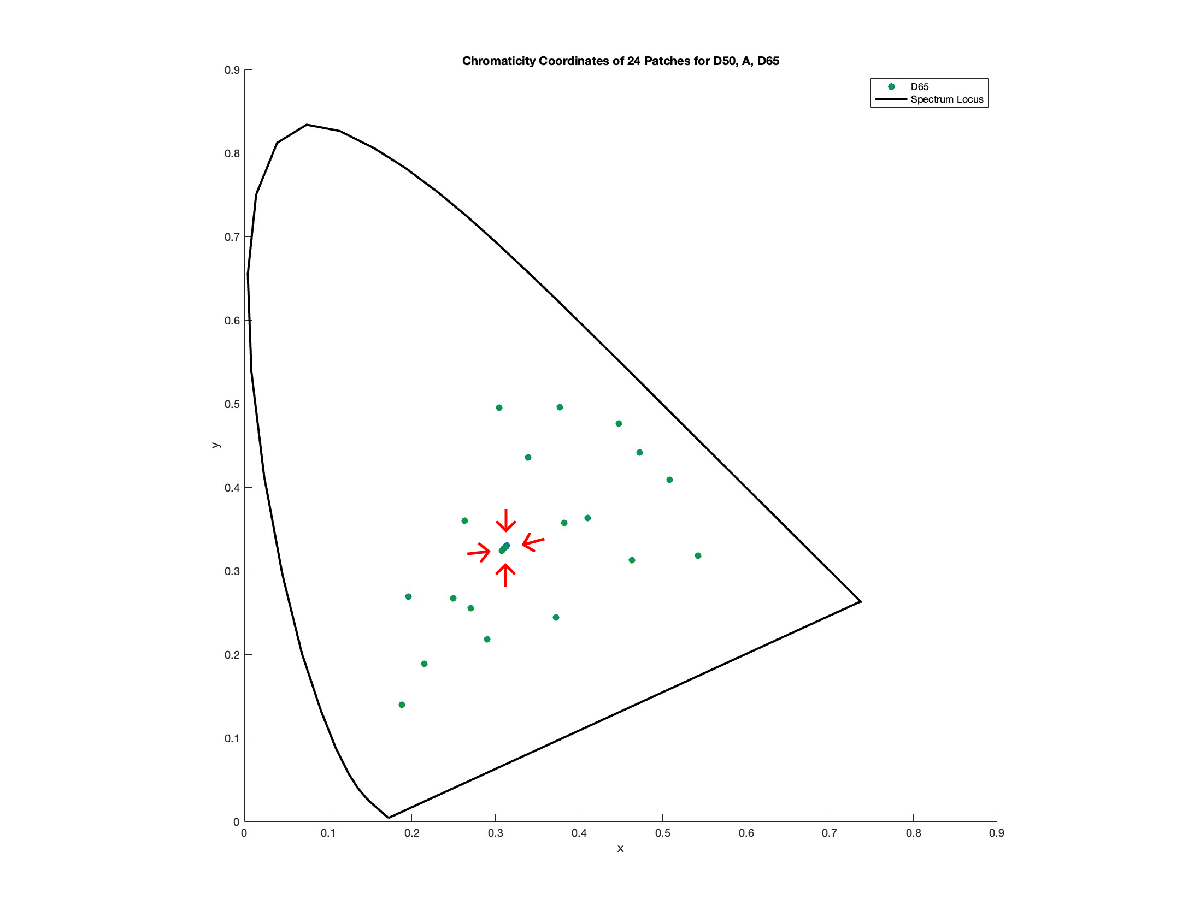

Image 1

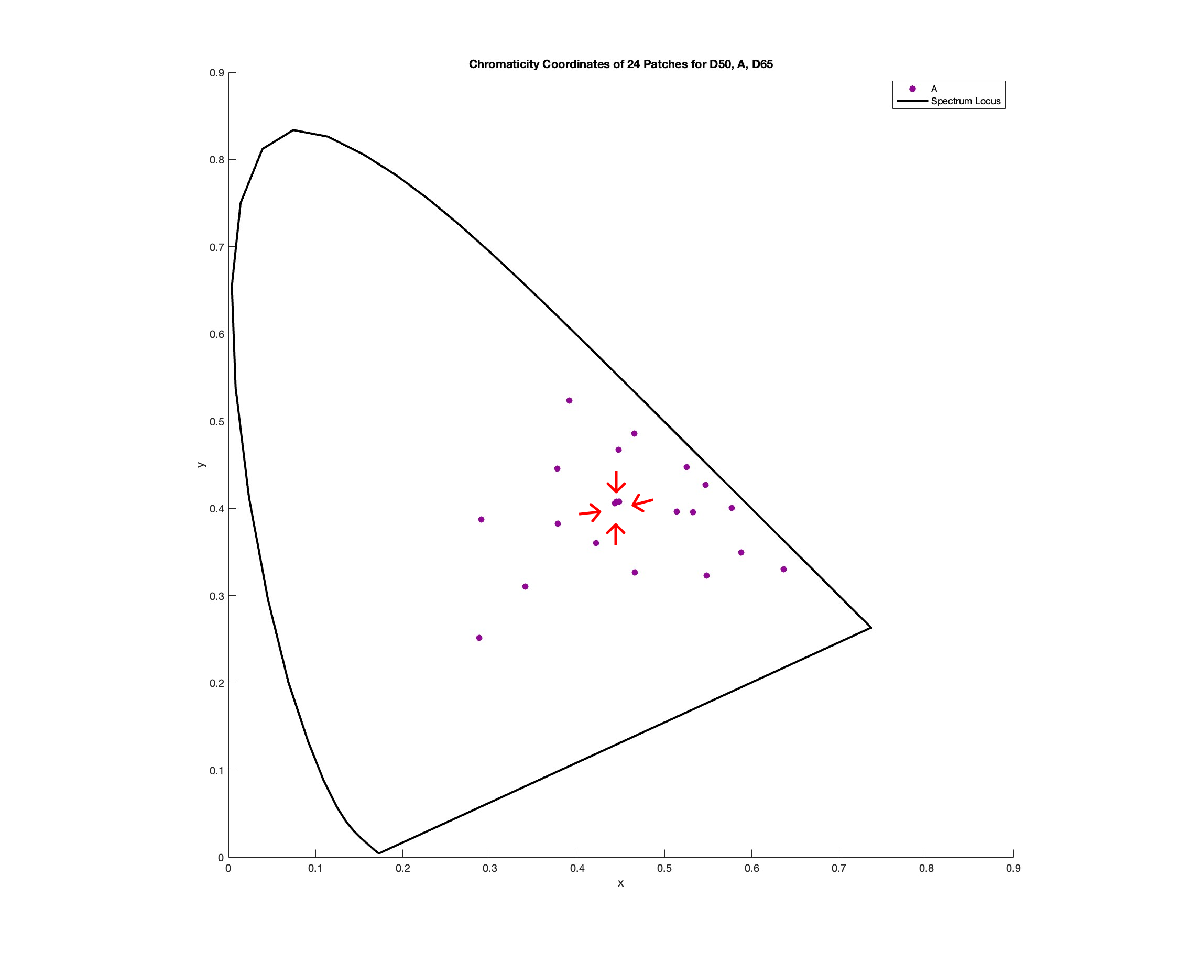

Image 2

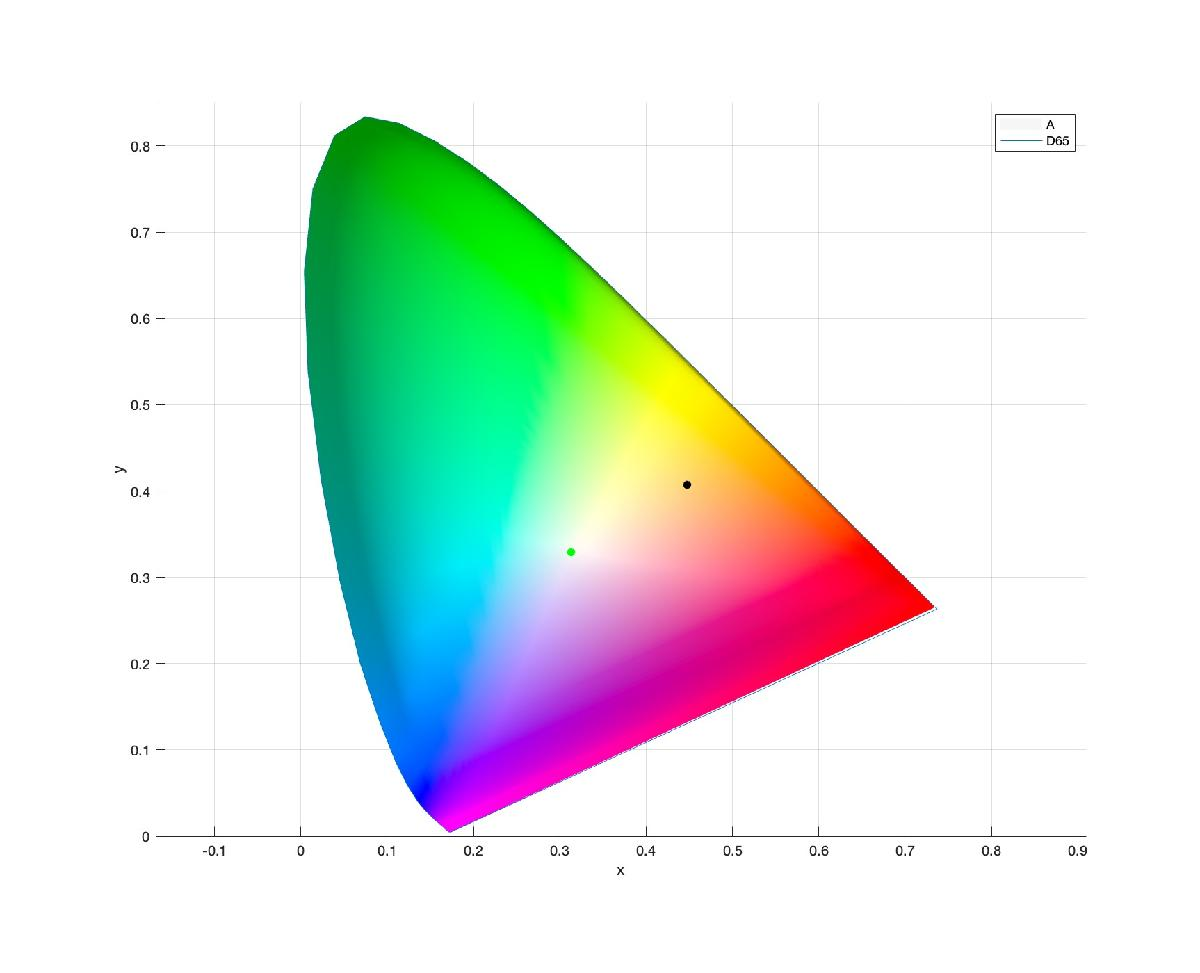

Image 3 (Incorrect legend in the image. Correct legend: Green - D65 illuminant; Black - A illuminant)

### Question 5

Why did I not ask you to plot the 10-deg (x,y) values with the rest?

**Answer:**

Plotting viewing angle will have impact on xyY 3d plot because viewing angle has significantly different value in z axis (lightness) due to changes in illuminant strength for 10 degree to tackle rod instrusion. So representing different degrees in 2d plot unit plane is insufficient and it should be projected different coordinate systems. Also, If we plot the 10 deg values along with 2-deg values in xy graph, the value will be overlapped in the plot since the value difference between 2-degree and 10-degree is less significant when compared to illuminant value difference.

### Question 7

Using the 2-deg XYZ values for both D65 and A illuminants, calculate CIELAB values (L*, a*, b*, and C*). Please put these in a table, one row per patch. Note that you will need to determine what you will use as your white XnYnZn for each calculation, and please list the values in your answer. 

- Calculated L*, a*, b* and C* using the below equation ( written as function in the end) 

 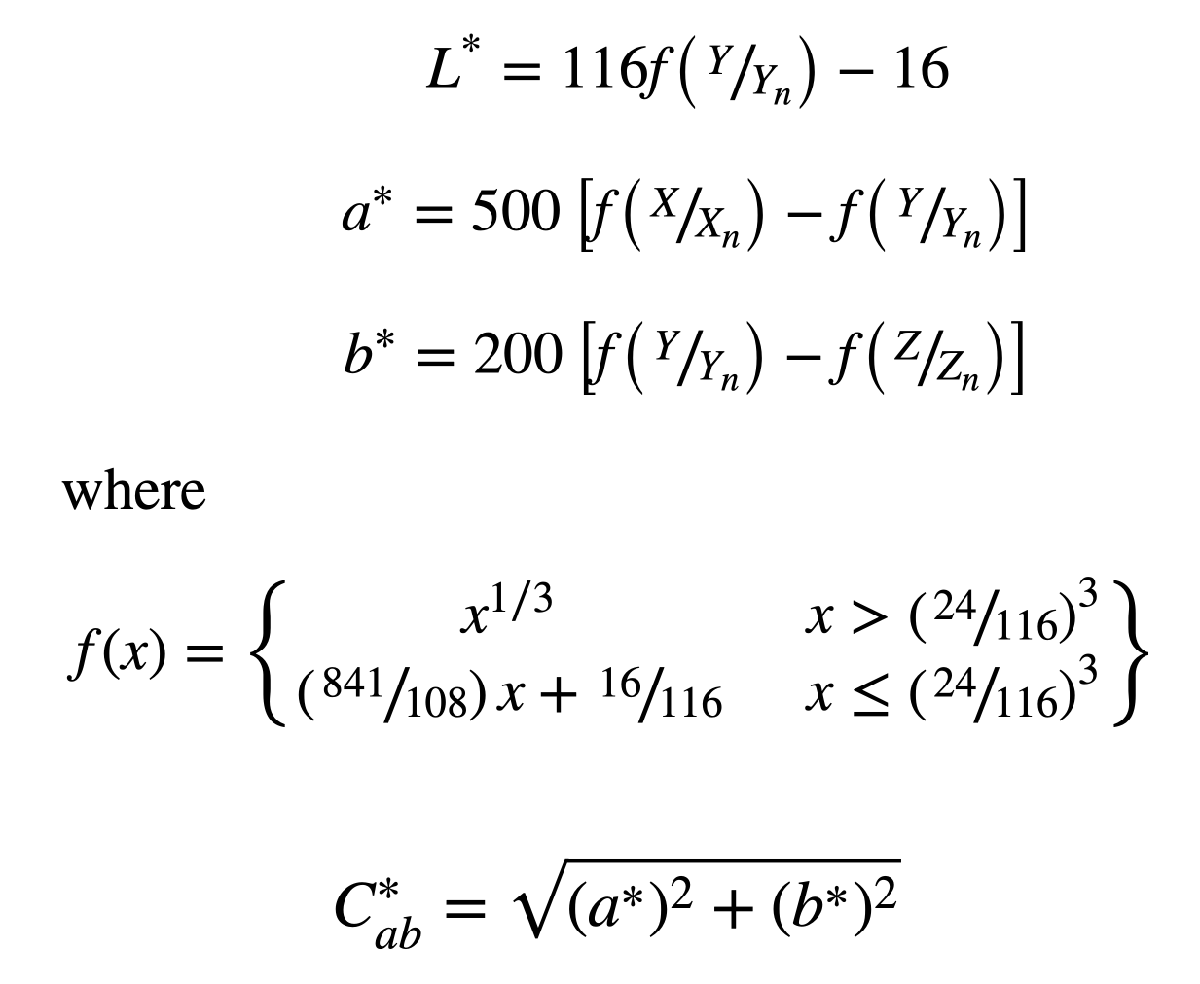

% Tristimulus value of Source A and Source D65 for 2 degree observer
wp_A_two_deg_source = calcTristimulusSource(xyz_std_obs_two_deg,sources_A,d_lambda);

ts =   109.8499  100.0000   35.5823


wp_D65_two_deg_source = calcTristimulusSource(xyz_std_obs_two_deg,sources_D65,d_lambda);

ts =    95.0426  100.0000  108.8785



% Chromaticity Coordinates of Source A and Source D65 for 2 degree observer
cc_wp_A_two_deg = calChromacityCoordinates(wp_A_two_deg_source');
cc_wp_D65_two_deg = calChromacityCoordinates(wp_D65_two_deg_source');

%Calculate L_star, a_star, b_star, C_star for all patches in A and D65 source 
[L_A, a_A, b_A, C_A] = calcXYZtoCIELAB(tristimulus_XYZ_A_two_deg,...
    wp_A_two_deg_source);
[L_D65, a_D65, b_D65, C_D65] = calcXYZtoCIELAB(tristimulus_XYZ_D65_two_deg,...
    wp_D65_two_deg_source);

### Question 7: Answer

Table_CIELAB_A = array2table([L_A; a_A; b_A; C_A]');
Table_CIELAB_A.Properties.VariableNames(1:4) = {'L*','a*','b*','C*'};
Table_CIELAB_A.Properties.Description = 'CIELAB of 24 patched for Illuminant A';
Table_CIELAB_A

Table_CIELAB_A = 24×4 table
      L*         a*         b*         C*  
    ______    ________    _______    ______

    39.544      16.837      19.28    25.597
    68.578      20.731     20.354    29.053
    48.985     -9.7193    -23.384    25.323
    42.306     -11.323     20.017    22.997
    55.867      6.6138    -24.249    25.135
    68.402      -30.41    -5.5113    30.905
    66.496       33.52     65.415    73.503
    38.562    -0.10231    -44.026    44.026
    56.583      47.727     25.407    54.068
    31.744      18.784    -17.656    25.779
    71.856     -17.005     52.138    54.841
    75.763      20.878     70.171    73.211
      27.1      2.5465    -54.065    54.125
    53.496     -36.187     27.189    45.264
    47.852      56.731     37.689    68.109
    84.411      9.8062     77.271     77.89


Table_CIELAB_D65 = array2table([L_D65; a_D65; b_D65; C_D65]');
Table_CIELAB_D65.Properties.VariableNames(1:4) = {'L*','a*','b*','C*'};
Table_CIELAB_D65.Properties.Description = 'CIELAB of 24 patched for Illuminant A';
Table_CIELAB_D65

Table_CIELAB_D65 = 24×4 table
      L*        a*         b*         C*  
    ______    _______    _______    ______

    37.304     13.692     15.564    20.729
      66.2     14.467      17.74    22.891
    50.781    -1.4728    -21.266    21.317
     42.74    -16.298     22.344    27.656
    56.468     11.518    -24.399    26.981
    71.371    -31.393     1.9816    31.455
    61.069     31.126     57.163    65.088
    40.828     15.397    -41.888    44.628
    50.952     45.921     15.086    48.335
    30.696     23.901    -22.073    32.534
    72.001    -27.183     58.033    64.084
    71.642     15.324     65.884    67.642
    29.986     24.609    -50.865    56.506
    55.655    -41.682     34.775    54.284
    40.937     52.848     25.607    58.725
    81.641    -1.5754     79.474     79.49


### Question 8:

Plot the L*, C* and a*, b* values of each patch on the a*b* and L*C* planes in CIELAB space (see the examples in the book for proper orientation, for example L* is typically the vertical axis). Make two sets of plots: one for D65 and one for A. Please label the points with patch number and/or color them appropriately. In these plots of a uniform color space, it is important to scale the x-axis and y-axis equally (*think about why*). In Matlab please use the command **axis equal**.

*Note: The patch number is added as text which will appear when the cursor is clicked on a plot value. This is done to minimize text noise in visualisation.*

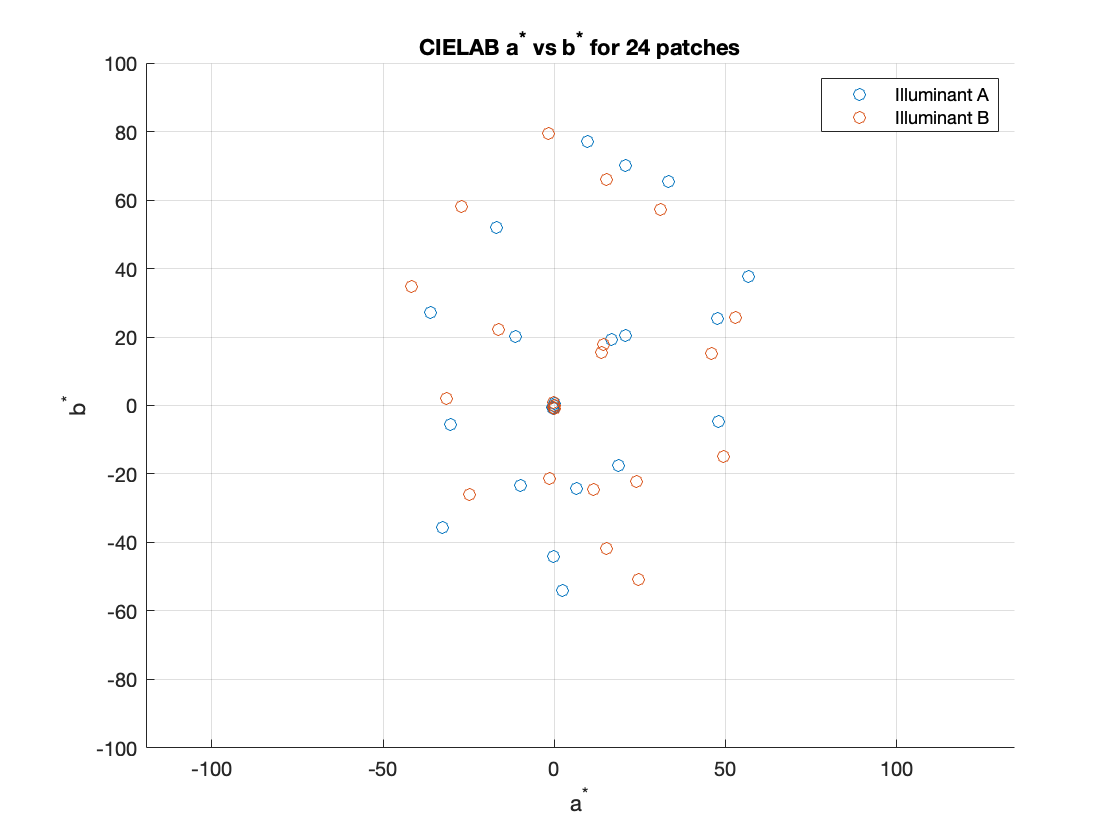

%Plot a against b under source A
figure;
hold on
s1 = scatter(a_A',b_A');
s2 = scatter(a_D65',b_D65');
legend([s1,s2], {'Illuminant A', 'Illuminant B'})
xlabel('a^{*}');
ylabel('b^{*}');
title('CIELAB a^{*} vs b^{*} for 24 patches');
xlim([-100 100]);
ylim([-100 100]);
axis equal
grid on
hold off

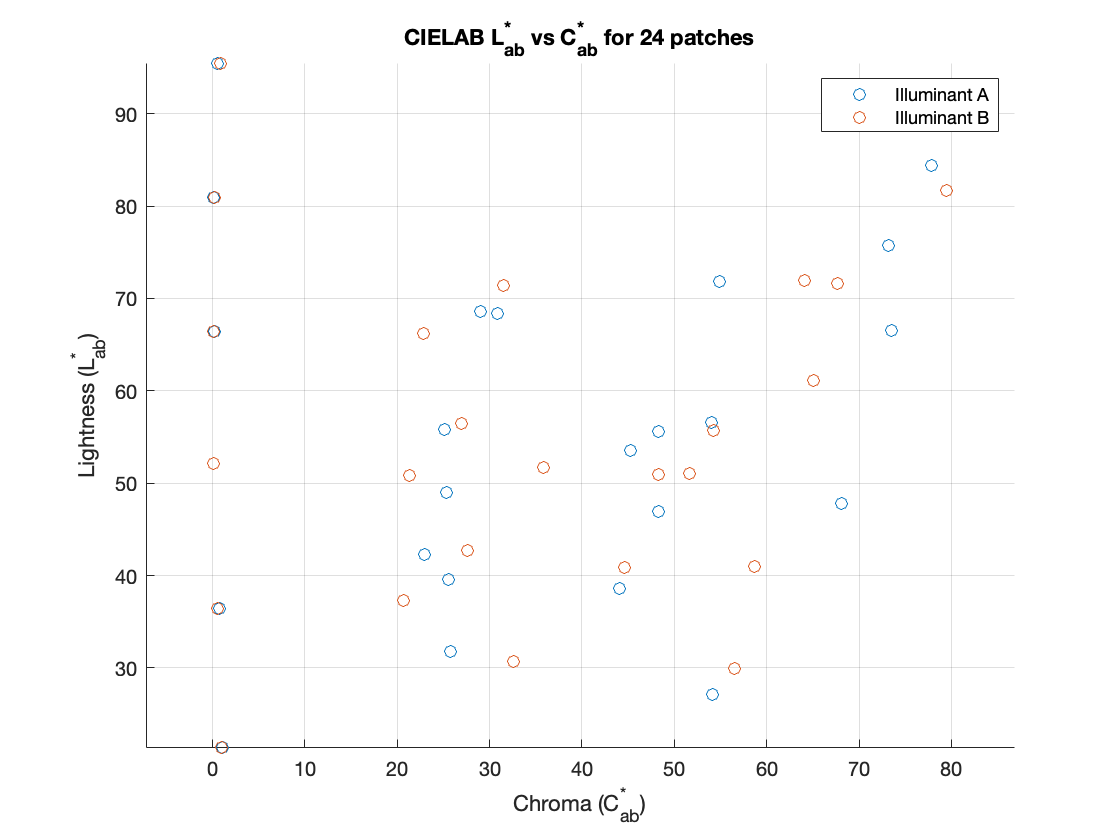

figure;
hold on
s3 = scatter(C_A',L_A');
s4 = scatter(C_D65',L_D65');
legend([s3,s4], {'Illuminant A', 'Illuminant B'})
xlabel('Chroma (C^{*}_{ab})');
ylabel('Lightness (L^{*}_{ab})');
title('CIELAB L^{*}_{ab} vs C^{*}_{ab} for 24 patches');
axis equal
grid on
hold off

### Question 9:

What do you observe about the locations of Color Checker patches on these plots for the different illuminants? How does the use of XnYnZn relate to what we did previously with von Kries chromatic adaptation?

**Observation in a* vs b* plot for illumination D65 and A**

In plotting the a* and b* graph, we could notice proper grouping of opponent colors - red against green in x axis representing a* value and yellow and blue in y axis representing b* value.

- Patches 8,10,13 represents the bluish purple shades in the patches. Since it is opponent to yellow in the repesentation, the illuminant A (which has yellowish impact) minimise the spread of these 3 patches in the plot when compared to illuminant D65.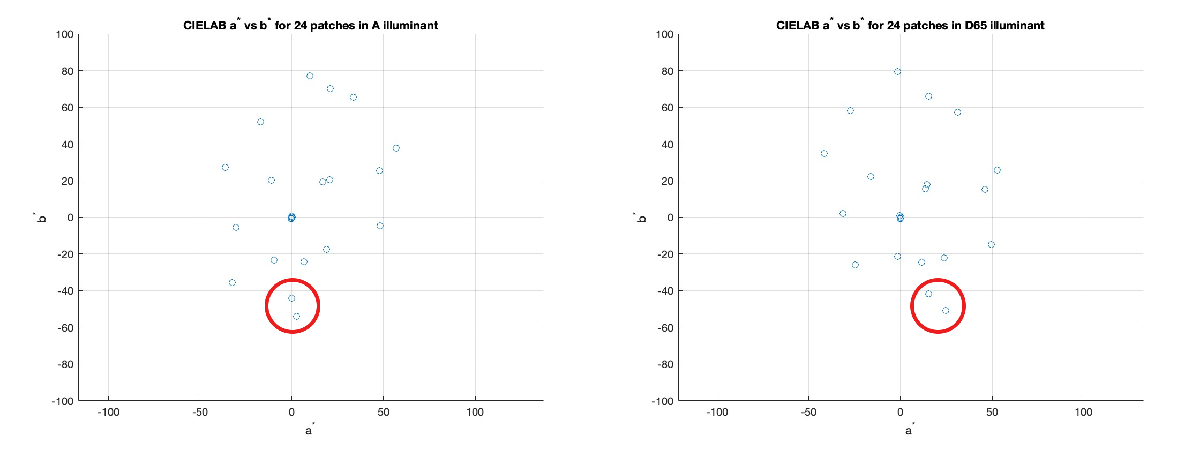

Image 1

- The greyscale patches of different lightness (19-24) are crowded at centre 0,0 in the plot. We couldn't notice the distinction in plotting due to graph's inability to represent lightness along an axis (Image 2).

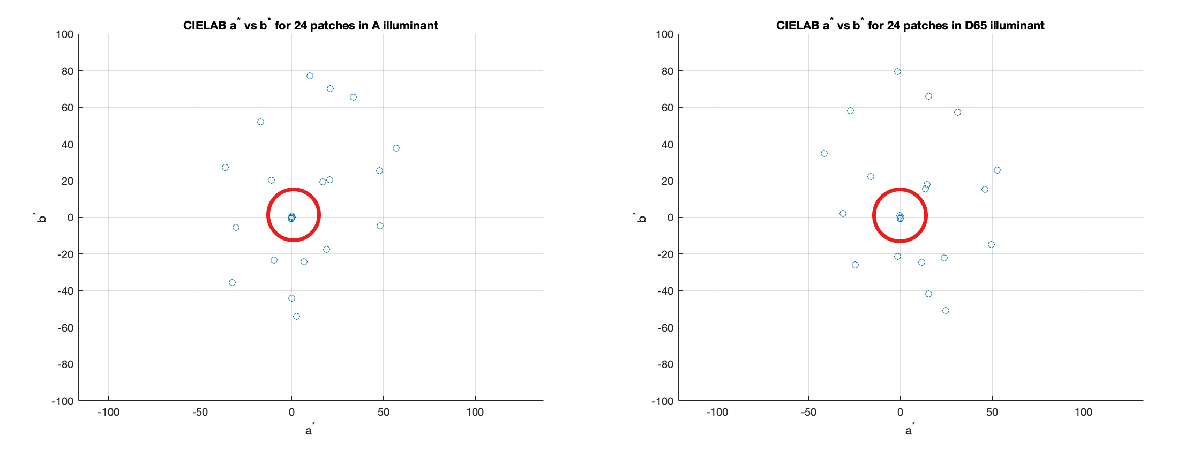

Image 2

**Observation in Lightness vs Chroma plot for illumination D65 and A**

- D65 have better distinction in chroma for the color patches when compared to illuminant A. This is very evident in image 3 where the patches located between chroma values 20 -30.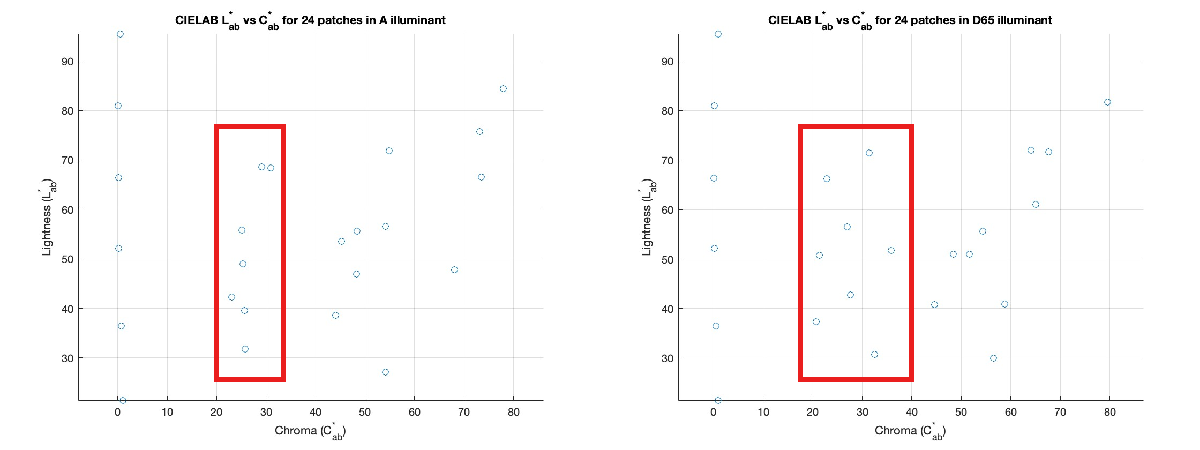                                                                    Image 3

- There is noticeable enhancement in chroma for yellow patches 7, 12, 16 in illuminant A when compated to illuminant D65. This is due to the yellowish nature of the illuminant A.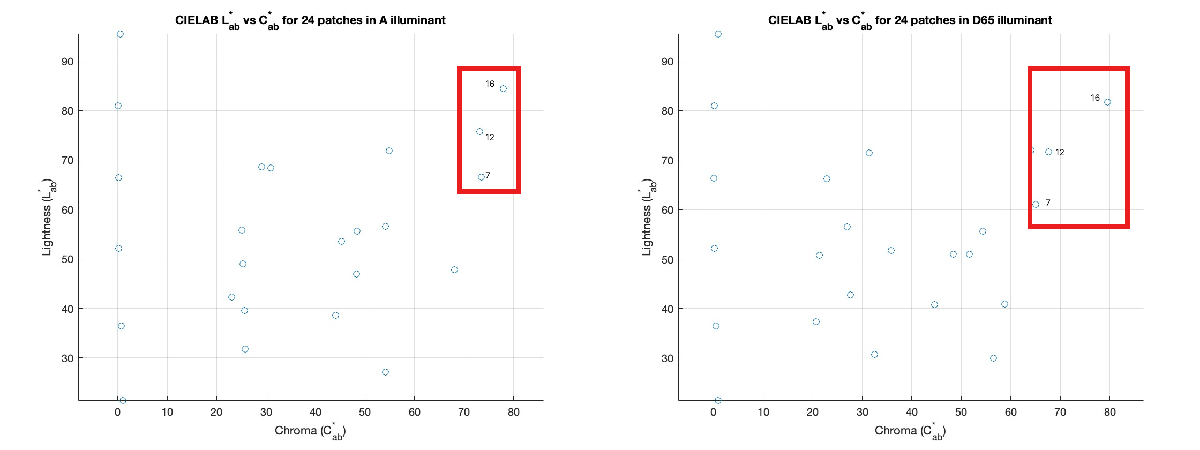

Image 4

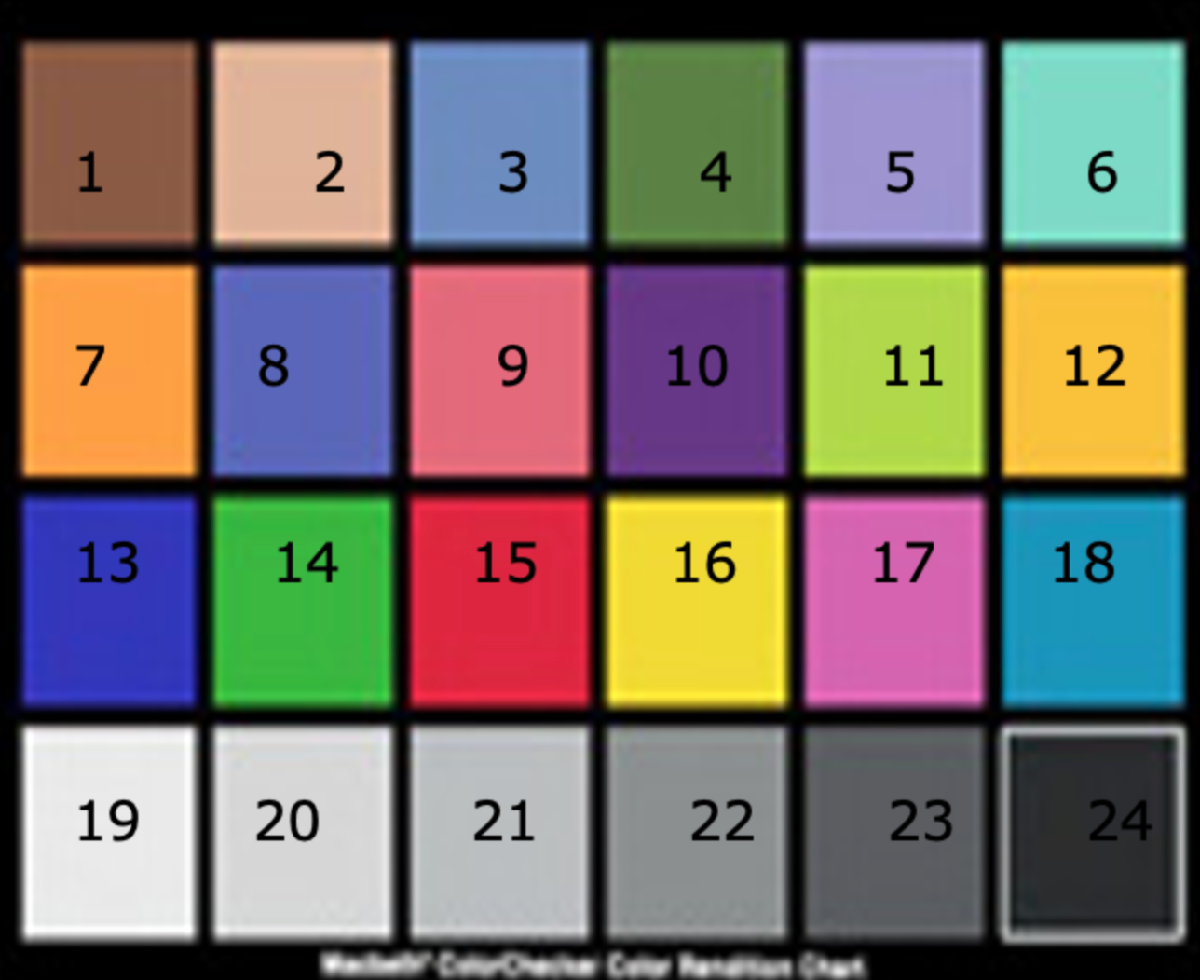

Image 5: 24 patches used for calculation

Von Kries model helps to predict the corresponding light under two 2 different illumination condition. The similar concept of normalising the calculated LMS value of material by LMS value of light source/white point is relatable in the Tristimulus calculation. Here, we are dividing the calculated Tristimulus value of the material by the tristimulus value of the source/white point (XnYnZn) to caluculate the XYZ primes. 

## Functions

%Function to interpolate the values to a consistent wavelength

function i = interpolateData(wavelengths,values,intp_wavelength_data)

    GI = griddedInterpolant(wavelengths,values);

    % Create a vector of query points with 5nm spacing for 380 to 780 wavelength.
    wl = intp_wavelength_data.min:intp_wavelength_data.range:intp_wavelength_data.max;

    % Evaluate the interpolant at the each wavelength for each value set 
    i = GI(wl);
end



%Function to calculate Tristimulus values for materials

function t = calcTristimulus(xyz_value,source,material,d_lambda)   

    %Calculate normalizing constant
    k = 100/(source * xyz_value(:,2) * d_lambda);

    s_lambda = diag(source);

    %Calculating tristimulus
    t = k.*((s_lambda*xyz_value)'*material)*d_lambda;

%   t = custom_normalization(t);
end


%Function to calculate Chromacity Coordinate
function cc = calChromacityCoordinates(tristimulus_XYZ)
    sum_XYZ = sum(tristimulus_XYZ,1);
    cc = tristimulus_XYZ./sum_XYZ;
end


%Function to calculate Tristimulus values for sources (Whitepoint)
function ts = calcTristimulusSource(xyz_value,source,d_lambda)   

    %Calculate normalizing constant
    k = 100/(source * xyz_value(:,2) * d_lambda);

    %Calculating tristimulus
    ts = k.*((source*xyz_value))*d_lambda

%   t = custom_normalization(t);
end


%Function to calculate CIELAB from XYZ
function [L_star,a_star,b_star,C_star] = calcXYZtoCIELAB(XYZ,whitepoint);
    XYZ_Prime = calcXYZPrime(XYZ,whitepoint);
    L_star = (116 * calConstants(XYZ_Prime(2,:))) - 16;
    a_star= 500*(calConstants(XYZ_Prime(1,:)) - calConstants(XYZ_Prime(2,:)));
    b_star = 200*(calConstants(XYZ_Prime(2,:)) - calConstants(XYZ_Prime(3,:)));
    C_star = ((a_star).^2 + (b_star).^2).^(1/2);
end


% Calculate X Prime, Y Prime and Z Prime
function XYZ_Prime = calcXYZPrime(XYZ,whitepoint)
    XYZ_Prime = XYZ./whitepoint';
end


%Function to calculate constants in a and b
function k = calConstants(x)
    if (x > (24/116)^3)
        k = (x).^(1/3);
    else
        k = ((841/108).*x) + (16/116);
    end
end


%Function to create table and assign x,y,z
function a2t = createTablexyz(values)
    a2t = array2table(values');
    a2t.Properties.VariableNames(1:3) = {'x','y','z'};
end


% Function to customize text of data tips in the plot
function txt = custom_label(~,event_obj)
pos = get(event_obj,'Position');
I = get(event_obj, 'DataIndex');
txt = {['X: ',num2str(pos(1))],...
       ['Y: ',num2str(pos(2))],...
       ['Patch: ',num2str(I)]};
end

% Function to normalize a matrix with its peak value
function n = custom_normalization(x)
    max_value = max(x, [], 'all');
    n = x/max_value;
end